# Using simulink to visualise system behaviour

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours. However, the real world is full of non-linear components and characteristics such as saturations, switches and non-simple shapes. In such cases non-linear models are needed and simulink is an ideal tool to capture this.

This livescript is a brief introduction to the use of simulink to model systems with some simple components. More importantly, it shows how integration with MATLAB code can make running the simulink file very efficient to allow systematic investigations for a range of parameter values. This livescript file makes use of the following files:

- simulink_openloop_model_control101.slx and simulink_openloop_model_control101_script.m

- simulink_openloop_modelb_control101.slx and simulink_openloop_modelb_control101_script.m

- simulink_openloop_modelc_control101.slx and simulink_openloop_modeld_control101_script.m

- simulink_openloop_modeld_control101.slx and simulink_openloop_modeld_control101_script.m

For more generic and comprehensive help on and introduction to Simulink, use the Mathworks onramp website. A number of other simple illustrations or case studies are described in the following livescripts and asssociated simulink files:

- car_suspension_simulink_control101.mlx  

- heating_system_simulink_control101.mlx   

- hydraulic_system_simulink_control101.mlx   

- position_system_simulink_control101.mlx

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**The next logical files are a sequence of case studies:**

- *car_suspension_simulink_control101   *

- *heating_system_simulink_control101*

- *position_system_simulink_control101 *

- *hydraulic_system_simulink_control101     *

- *submersible_simulink_control101  *  

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Preamble

We deliberately avoid a slow introduction using simple sinks, sources and scopes and running simulink directly from the simulink file because we want to focus quickly on how simulink can be used efficiently in combination with MATLAB and to produce nice plots and for systematic design. Ultimately many simulink files have a large number of parameters which are most conveniently defined with a supporting MATLAB script and thus one might as well run the simulink file directly from the same script and produce neat plots rather than using scopes.

Moreover, we focus sinks and sources on the options which **import and export data to the main MATLAB workspace** so the values can be used elsewhere as needed, for example in plotting.

For more generic and comprehensive help on and introduction to Simulink, use the Mathworks onramp website.

## 1. Simple car speed model

We consider a car can be represented as a simple mass-damper model, the damping representing friction which is assumed proportional to velocity. So with mass *M*, damping *B *which represents frictional forces,  throttle position *f *(assume values between 0 and 1), and C relates to the maximum engine power available, the model is:

$M\frac{\textrm{dv}}{\textrm{dt}}+\textrm{Bv}=\textrm{Cf}$      or         $v\left(s\right)=\frac{C}{\textrm{Ms}+B}f\left(s\right)=G\left(s\right)f\left(s\right)$

A simple simulink file looks like the following:

 

**Figure 1**: Screen capture of ***simulink_openloop_model_control101.slx***

- We need to define the throttle profile as a function of time in the 'From Workspace' Block.

- We need to define the format desired for ouput variable from the 'To workspace' block labelled speed and throttle. Here we have used 'Structure with time'.

- We need to define the variables in the car model, that is, num(s) and den(s); these values will be picked up from the workspace. Note the value highlighted in yellow below is a simulink generated warning that this variable is not yet defined in the workspace.

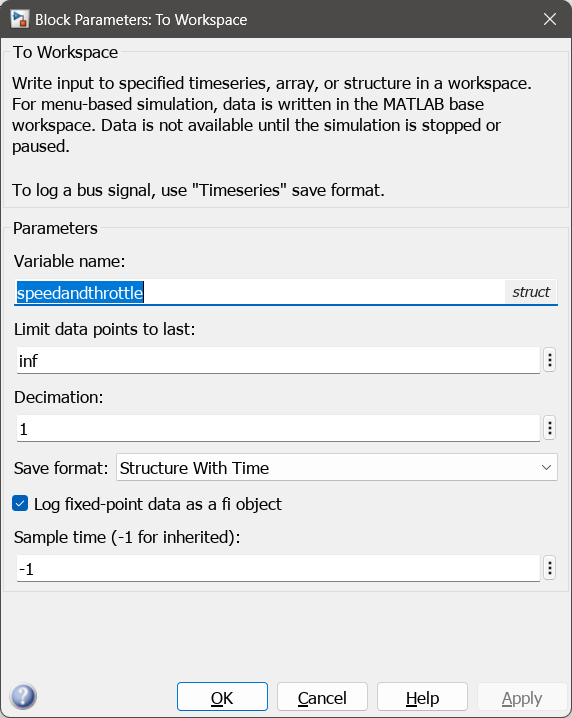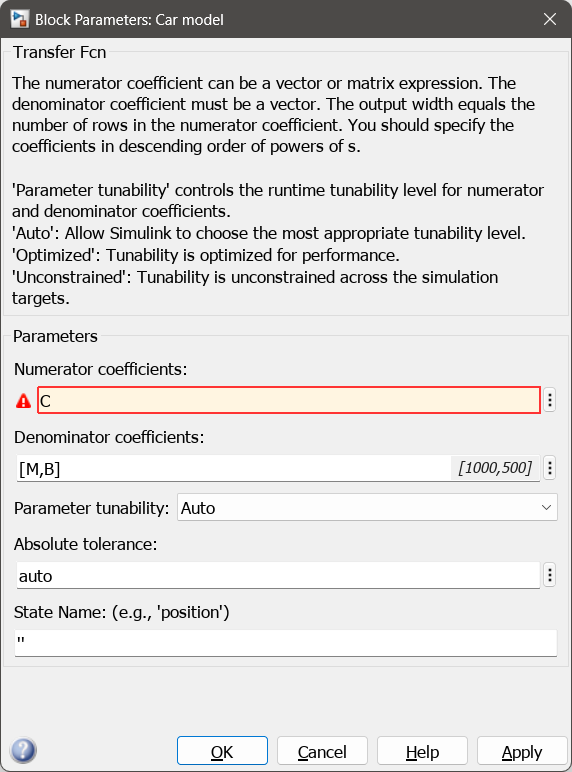

The associated code to define the required parameters,  run this simulink file (***simulink_openloop_model_control101.slx***) and then produce a plot based on the output, is given in ***simulink_openloop_model_control101_script.m***. Users can change the parameter values and use run file to investigate further, or indeed embed all the code here if that is more convenient. 

%open simulink_openloop_model_control101_script.m
disp('*****************************')
disp('Section 1 illustrations below')
run simulink_openloop_model_control101_script.m

## 2. Adding disturbances into the simulink model

In practice the road may not be level and have a slope $\theta$. Also there may be wind of speed *w*. These two factors affect the model in the following way.

 $M\frac{\textrm{dv}}{\textrm{dt}}+B\left(v+w\right)+\textrm{Mgsin}\left(\theta \right)=\textrm{Cf}$    [Hereafter assume small angles so $\theta =\sin \left(\theta \right)$.]

Hence, this can be represented as a transfer function model with one output (velocity) and three inputs (throttle, slope, wind).


$$v\left(s\right)=\frac{C}{\textrm{Ms}+B}f\left(s\right)-\frac{\textrm{Mg}}{\textrm{Ms}+B}\theta \left(s\right)-\frac{B}{\textrm{Ms}+B}w\left(s\right)$$


We can easily augment the simulink diagram to include these impacts by adding the appropriate transfer function blocks and also 'from workspace' blocks to define the profiles of the slope and wind. We can also adding a summing junction to add all the speed effects together. While this diagram (***simulink_openloop_modelb_control101.slx***)  is a little messy, it demonstrates the ease with which mutliple inputs and blocks can be incorporated.

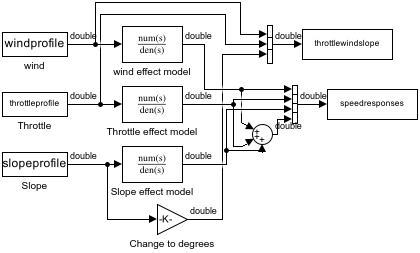

**Figure 2**: Screen capture of ***simulink_openloop_modelb_control101.slx***

To see the parameter definitions or run the associated code, use the following:

%open simulink_openloop_modelb_control101_script.m
disp('*****************************')

*****************************


disp('Section 2 illustrations below')

Section 1 illustrations below


speedandthrottle = struct with fields:
         time: [61×1 double]
      signals: [1×1 struct]
    blockName: 'simulink_openloop_model_control101/To Workspace'


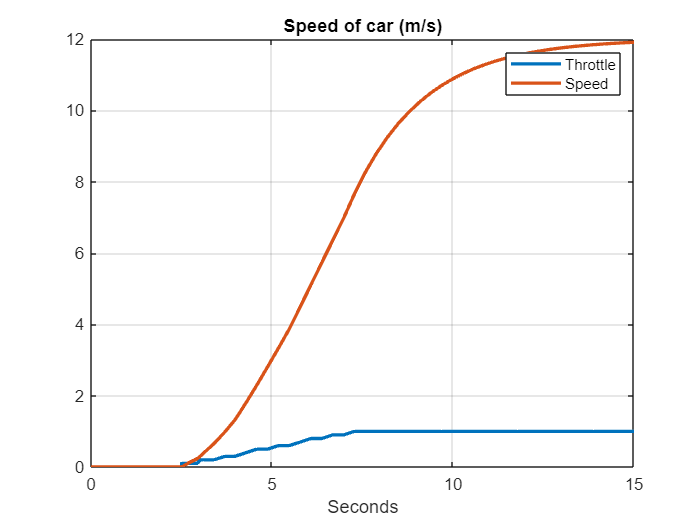

run simulink_openloop_modelb_control101_script.m

## 3. Illustration of non-linear effects

Next we might want to consider that the system has non-linear attributes and ask how these can be incorporated. This section illustrates just a few and it is left to the reader to experiment with a wider range of options available in the simulink library. To aid transparency, we use a simpler block diagram.

### 3.1 Simple gearing

We will use a simplified model for the impact of gearing on the car speed, so in essence a change in gear leads to a change in the force available on the raod, that is, a change in parameter *'C*'.

An easy way to implement this for illustration is fixing timing for the changes in *C* though an input and doing a multipy.

$M\frac{\textrm{dv}}{\textrm{dt}}+\textrm{Bv}=C\left(t\right)f$     where *C(t)* has a small number of distinct values according to some switching. 

Here for simplicity, we use: $C\left(t\right)=C\;k\left(t\right)$; where *k(t) *(denoted the gear profile) takes simple values to represent a change in gear.

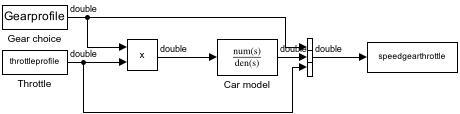

**Figure 3**: Screen capture of ***simulink_openloop_modelc_control101.slx***

To see the parameter definitions or run the associated code, use the following:

%open simulink_openloop_modelc_control101_script.m
disp('*****************************')

*****************************


disp('Section 3.1 illustrations below')

Section 2 illustrations below


speedandthrottle = struct with fields:
         time: [61×1 double]
      signals: [1×1 struct]
    blockName: 'simulink_openloop_model_control101/To Workspace'


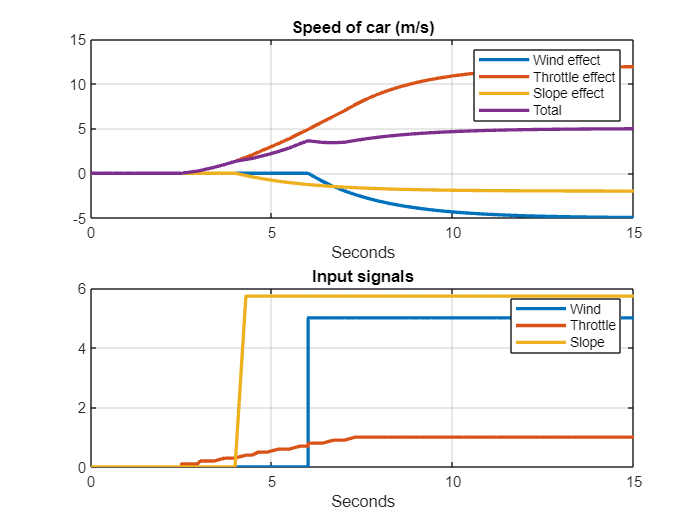

run simulink_openloop_modelc_control101_script.m

### 3.2 Rate limits

Some engines do not like rapid changes in throttle as this can cause flooding, so the throttle should be increased more slowly. Simulink has numerous tools to allow easy handling of such scenarios as shown in the following example where a simple rate limit of 10% per second is placed on the throttle. The figure shows the demand sent to the throttle and what is actual delivered after the constraint is applied. A gear change is also included.

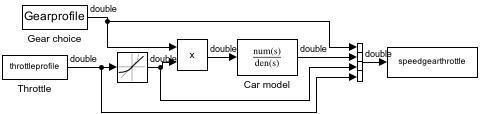

**Figure 4**: Screen capture of ***simulink_openloop_modeld_control101.slx***

To see the parameter definitions or run the associated code, use the following:

%open simulink_openloop_modeld_control101_script.m
disp('*****************************')

*****************************


disp('Section 3.2 illustrations below')

Section 3.1 illustrations below


speedgearthrottle = struct with fields:
         time: [57×1 double]
      signals: [1×1 struct]
    blockName: 'simulink_openloop_modelc_control101/To Workspace'


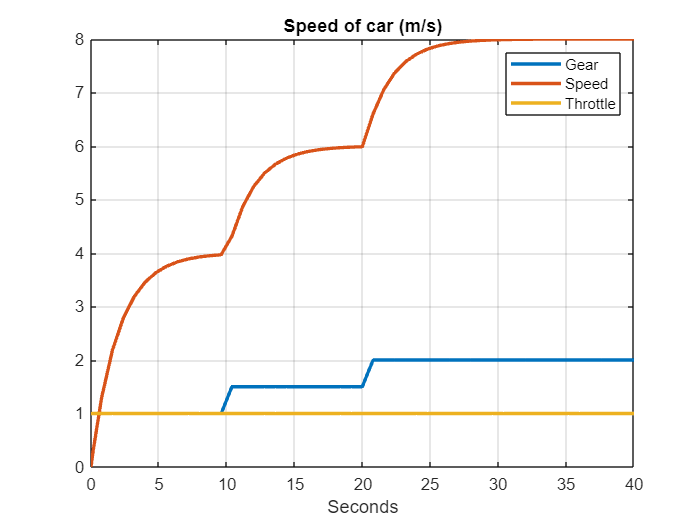

*****************************


Section 3.2 illustrations below


speedgearthrottle = struct with fields:
         time: [55×1 double]
      signals: [1×1 struct]
    blockName: 'simulink_openloop_modeld_control101/To Workspace'


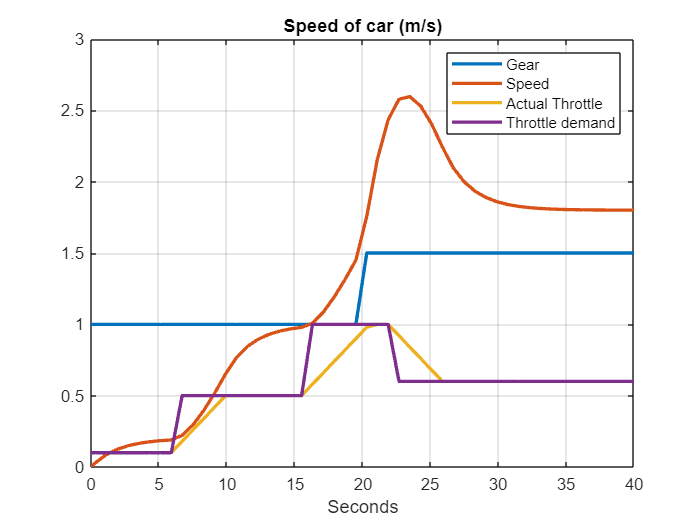

run simulink_openloop_modeld_control101_script.m